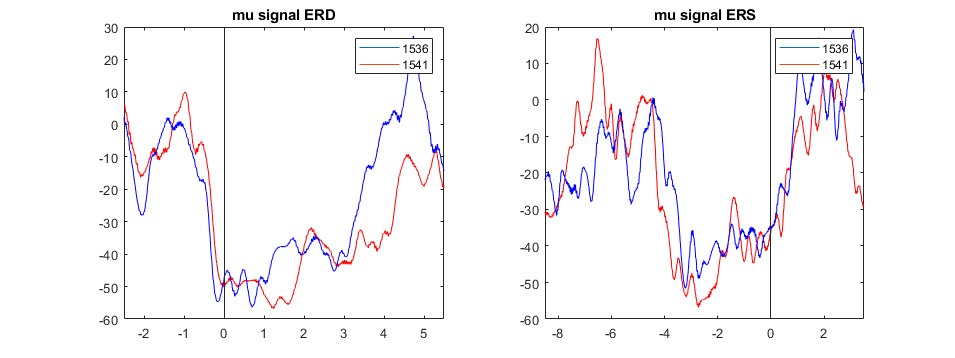

% [grand_mean_mu_1541,grand_mean_beta_1541,ERD_mu_1541,ERD_beta_1541,grand_mean_mu_ERP_1541,grand_mean_beta_ERP_1541,ERP_mu_1541,ERP_beta_1541] = D6_function(1541,[false,true],subject_list,data,icadata, true);
% [grand_mean_mu_1536,grand_mean_beta_1536,ERD_mu_1536,ERD_beta_1536,grand_mean_mu_ERP_1536,grand_mean_beta_ERP_1536,ERP_mu_1536,ERP_beta_1536] = D6_function(1536,[false,true],subject_list,data,icadata, true);
% 

t=-2.5+1/512:1/512:5.5;
t_ERP = -8.5+1/512:1/512:3.5;

G1=figure(1);
set(G1,'Position',[10 10 2000 750]);
subplot(1,2,1)
plot(t,grand_mean_mu_1536(28,:),'red')
hold on 
plot(t,grand_mean_mu_1541(28,:),'blue')
xline(0);xlim([-2.5 5.5]);legend('1536','1541');title('mu signal ERD')

subplot(1,2,2)
plot(t_ERP,grand_mean_mu_ERP_1536(28,:),'red')
hold on 
plot(t_ERP,grand_mean_mu_ERP_1541(28,:),'blue')
xline(0);xlim([-8.5 3.5]);legend('1536','1541');title('mu signal ERS')

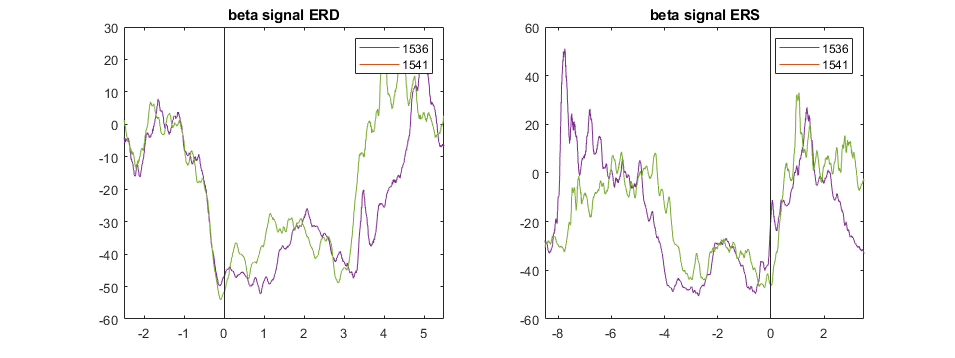



G2=figure(2);
subplot(1,2,1)
plot(t,grand_mean_beta_1536(28,:))
hold on 
plot(t,grand_mean_beta_1541(28,:))
xline(0);xlim([-2.5 5.5]);legend('1536','1541');title('beta signal ERD')

subplot(1,2,2)
plot(t_ERP,grand_mean_beta_ERP_1536(28,:))
hold on 
plot(t_ERP,grand_mean_beta_ERP_1541(28,:))
xline(0);xlim([-8.5 3.5]);legend('1536','1541');title('beta signal ERS')

set(G2,'Position',[10 10 2000 750]);


% figure
% plot(t,grand_mean_beta_1536(28,:))
% hold on 
% plot(t,grand_mean_beta_1541(28,:))
% xline(0);xlim([-2.5 5.5]);
% legend('1536','1541')
% figure
% plot(t,grand_mean_beta_1536(28,:))
% hold on 
% plot(t,grand_mean_mu_1536(28,:))
% xline(0);xlim([-2.5 5.5]);
% legend('beta','mu')

eeglab;close;
waitfor(msgbox("Now, please select your loc file without EOG channels", 'Loc file selection'));
[locs_noica,locpath_noica]=uigetfile('*.loc', 'Pick a channel location file');
locpath_noica=strrep(locpath_noica,'\','\\'); %for windows
locs_noica=append(locpath_noica,locs_noica);

H1=figure(10);
subplot(1,2,1)
D7_topoplots(grand_mean_mu_1536,locs_noica);
subplot(1,2,2)
D7_topoplots(grand_mean_mu_1541,locs_noica);
set(H1,'Position',[10 10 2000 750]);

H2=figure(11);
subplot(1,2,1)
D7_topoplots(grand_mean_beta_1536,locs_noica);
subplot(1,2,2)
D7_topoplots(grand_mean_beta_1541,locs_noica);
set(H2,'Position',[10 10 2000 750]);
